# Importing Tsunami Occurrence Data for Regional Visualizations and Prediction Model Creation

Data was obtained from the following file: [tsunamis.xlsx](matlab:open('./tsunamis.xlsx')). For more details on column variables, explore [tsunamis.txt](matlab:open('./tsunamis.txt')).

### 1) Import Data

Import data from an Excel spreadsheet and keep the tabular format.

data1 = readtable('tsunamis.xlsx') % read 'tsunamis.xlsx' table data into data1

data1 = 162×20 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode            Validity             CauseCode               Cause                EarthquakeMagnitude          Country                         Location                   MaxHeight    IidaMagnitude    Intensity    NumDeaths    DescDeaths
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    _________________________    _________

#### 2) Visualize the data

Display the latitude and longitude values.

geobubble: Visualize data values at specific geographic locations

% Visualize the Cause of Tsunami in different colors against Latitude & Longitude
geobubble(data1.Latitude, data1.Longitude, 'ColorData', categorical(data1.Cause)) 

Apply a colorterrain basemap to this visualization.

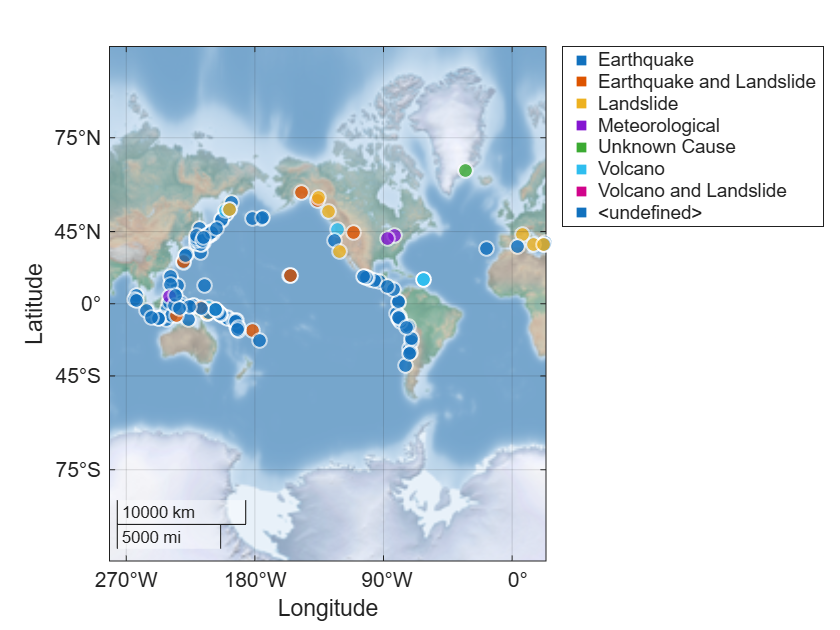

geobasemap colorterrain % Apply a colorterrain basemap to this visualization.

#### 3) Select specified columns

data2 = data1(:, {'Latitude', 'Longitude', 'EarthquakeMagnitude', ...
    'IidaMagnitude', 'Intensity', 'MaxHeight', 'Validity', 'Location', 'Country'}) % extracting only the selected columns from data1 and saved in data2

data2 = 162×9 table
    Latitude    Longitude    EarthquakeMagnitude    IidaMagnitude    Intensity    MaxHeight            Validity                           Location                         Country       
    ________    _________    ___________________    _____________    _________    _________    _________________________    _____________________________________    ____________________

       -3.8        128.3             7.6                 1.5            1.5           2.8      {'questionable tsunami' }    {'JAVA TRENCH, INDONESIA'           }    {'INDONESIA'       }
       19.5         -156             6.9                 1.8            NaN           3.6      {'definite tsunami' 

#### 4) Remove rows with NaN or missing values

rmmissing: Remove missing entries or removes rows containing NaN

data2 = rmmissing(data2) % removes rows containing NaN in data2

data2 = 77×9 table
    Latitude    Longitude    EarthquakeMagnitude    IidaMagnitude    Intensity    MaxHeight            Validity                         Location                     Country   
    ________    _________    ___________________    _____________    _________    _________    ________________________    ___________________________________    _____________

       -3.8        128.3             7.6                 1.5            1.5           2.8      {'questionable tsunami'}    {'JAVA TRENCH, INDONESIA'         }    {'INDONESIA'}
      42.15       143.85             8.1                 2.7              2           6.5      {'definite tsunami'    }    {'SE. HOKKAIDO ISLAND' 

#### Exploration of creating a machine learning model to see if: tsunami intensity could be modeled from the predictors of Earthquake magnitude, Iida magnitude, and tsunami height

#### 5) Creating the Training and Test indices for cross validation

% crossvalind: Generate indices for training and test sets
[train, test] = crossvalind('HoldOut', length(data2.Intensity), 0.1)

train = 77×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1


test = 77×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


#### 6) Extracting the Training data & Test data

% extracting the Training data from data2 using train
train_data = data2(train, :)

train_data = 70×9 table
    Latitude    Longitude    EarthquakeMagnitude    IidaMagnitude    Intensity    MaxHeight            Validity                         Location                     Country   
    ________    _________    ___________________    _____________    _________    _________    ________________________    ___________________________________    _____________

       -3.8        128.3             7.6                 1.5            1.5           2.8      {'questionable tsunami'}    {'JAVA TRENCH, INDONESIA'         }    {'INDONESIA'}
      42.15       143.85             8.1                 2.7              2           6.5      {'definite tsunami'    }    {'SE. HOKKAIDO ISL

% extracting the Test data from data2 using test
test_data = data2(test, :)

test_data = 7×9 table
    Latitude    Longitude    EarthquakeMagnitude    IidaMagnitude    Intensity    MaxHeight          Validity                    Location                    Country       
    ________    _________    ___________________    _____________    _________    _________    ____________________    ____________________________    ____________________

       16.5         -99              7.9                 1.3            1.5          2.5       {'definite tsunami'}    {'S. MEXICO'               }    {'MEXICO'          }
       61.1      -147.5              9.2                 6.1              5           67       {'definite tsunami'}    {'PRINCE WILLIAM SOUND, AK'}    {'US

% List variables train_data & test_data in workspace, with sizes and types
whos train_data test_data 

  Name             Size            Bytes  Class    Attributes

  test_data        7x9              6481  table              
  train_data      70x9             36855  table              



## 7) Regression Learner App

Open up the Regression Learner App.

regressionLearner 

Import data from the table into this tool.

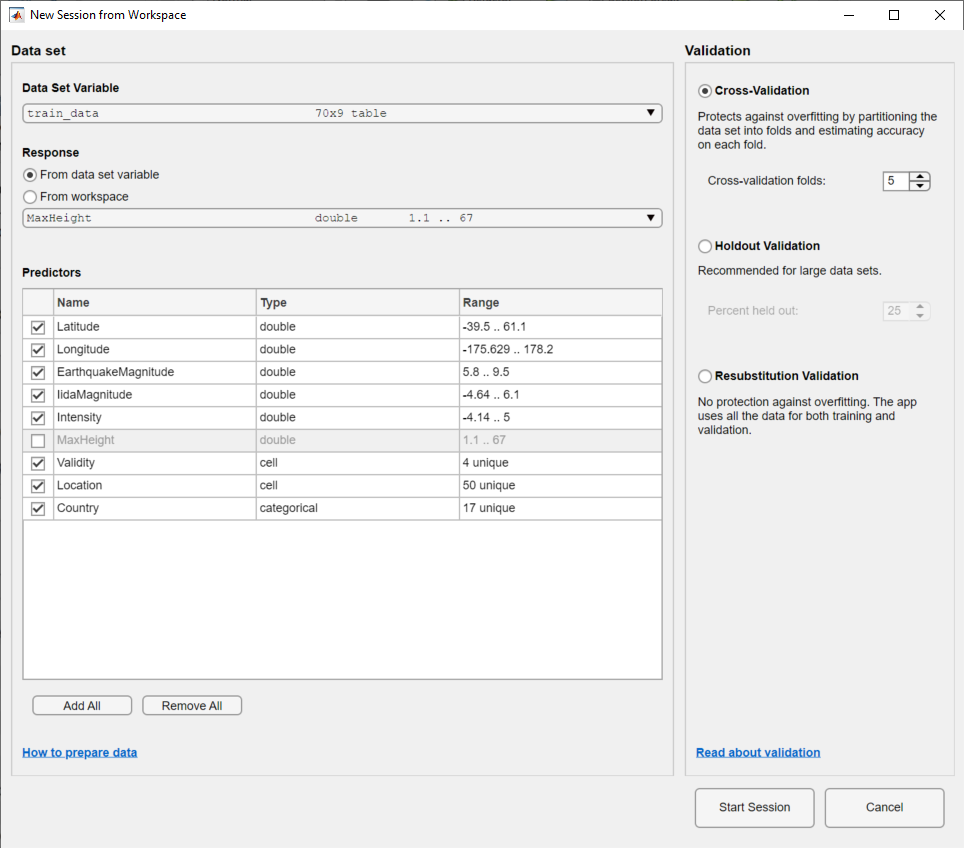

Select response and predictor variables.

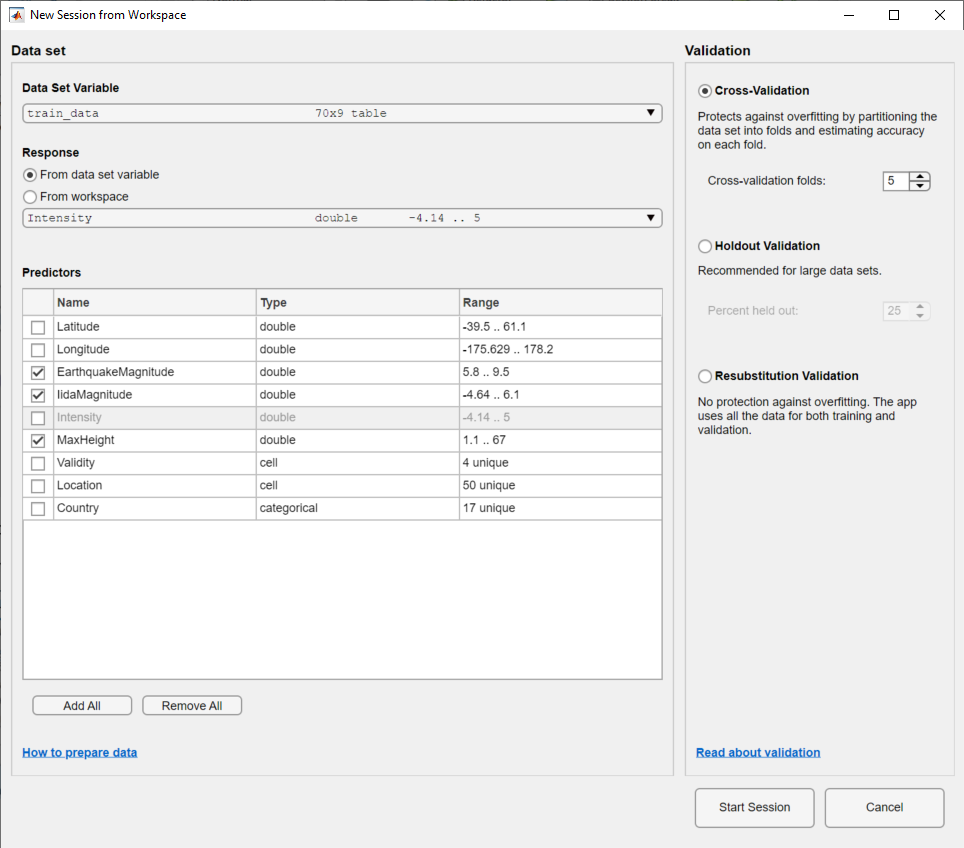

Select the Start Session button to move forward (the default settings for Validation were used).

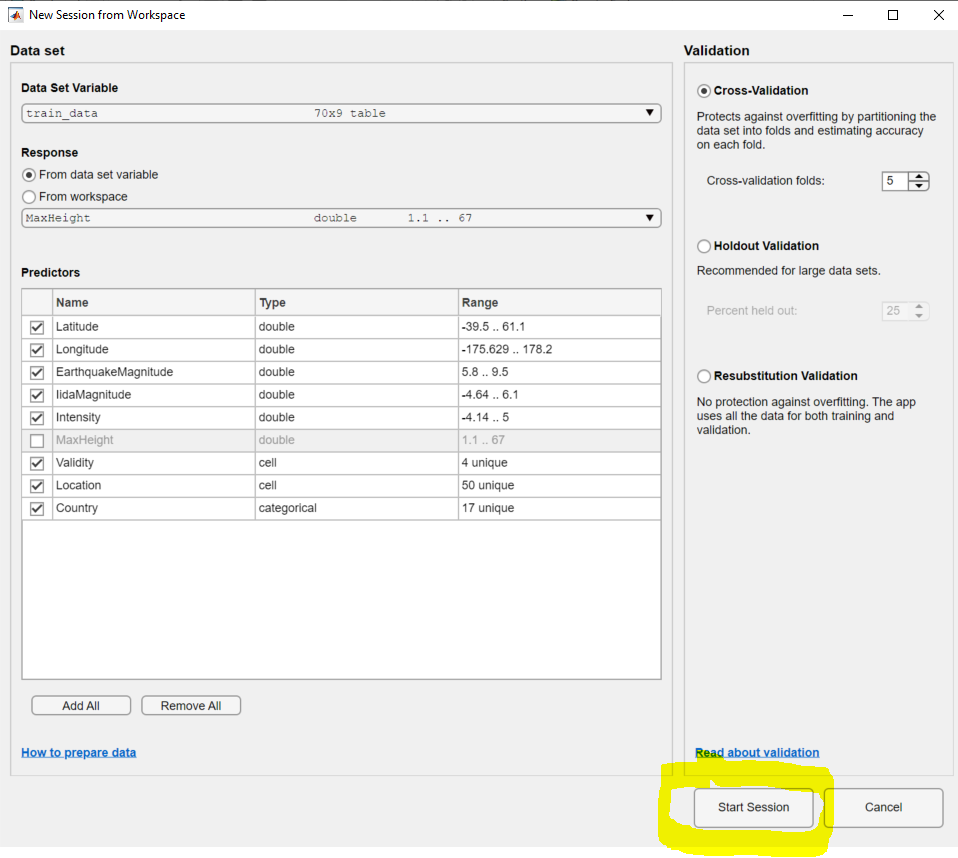

View a response plot with respect to the Intensity (on the y axis) and one of the predictors (in this case IidaMagnitude on the x axis).

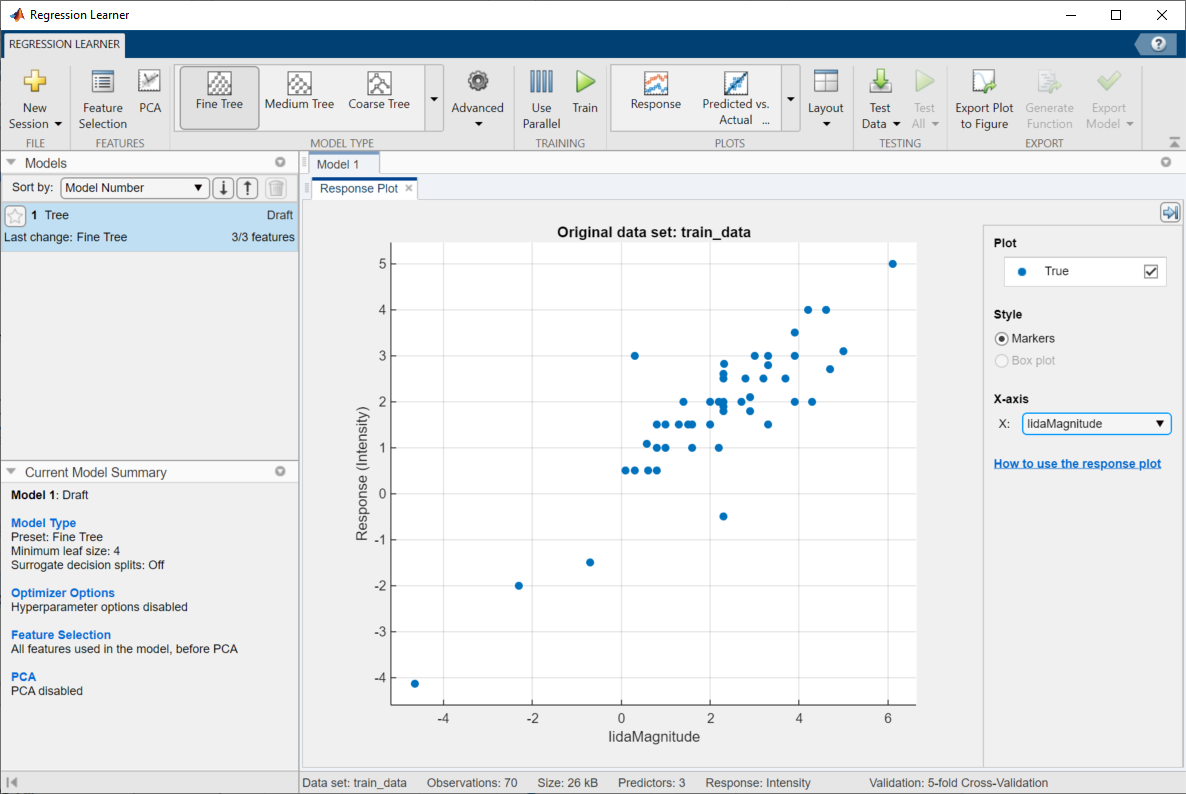

Explore model type to use for this Machine Learning model and select an option (or several).

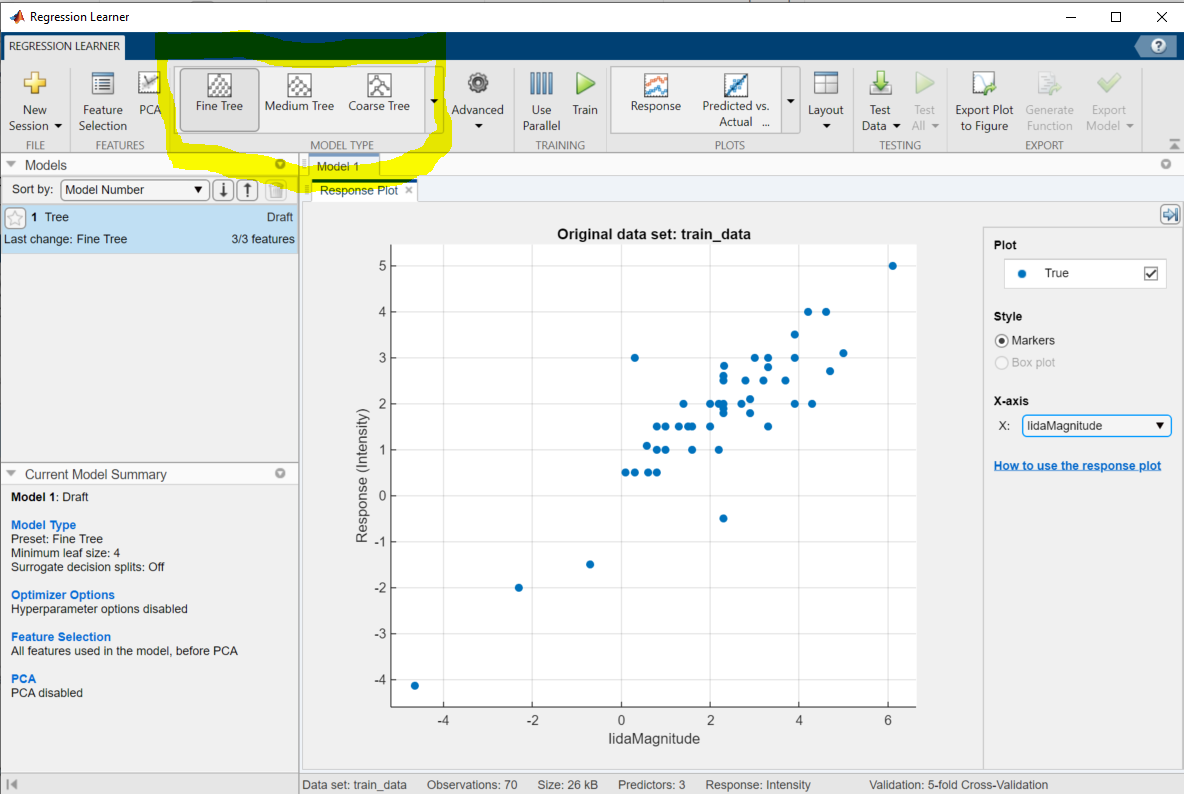

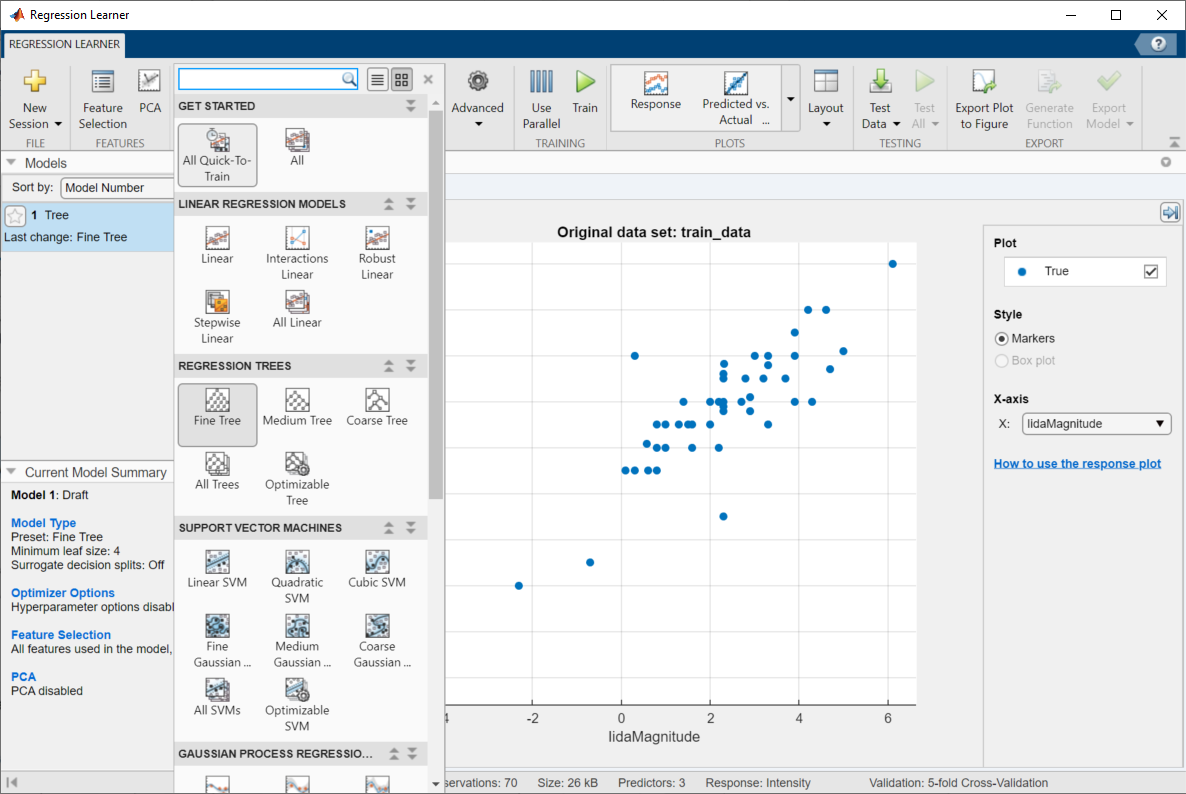

The All Quick-to-Train option was selected to quickly train several models and to start training the Train button in the Training section was selected.

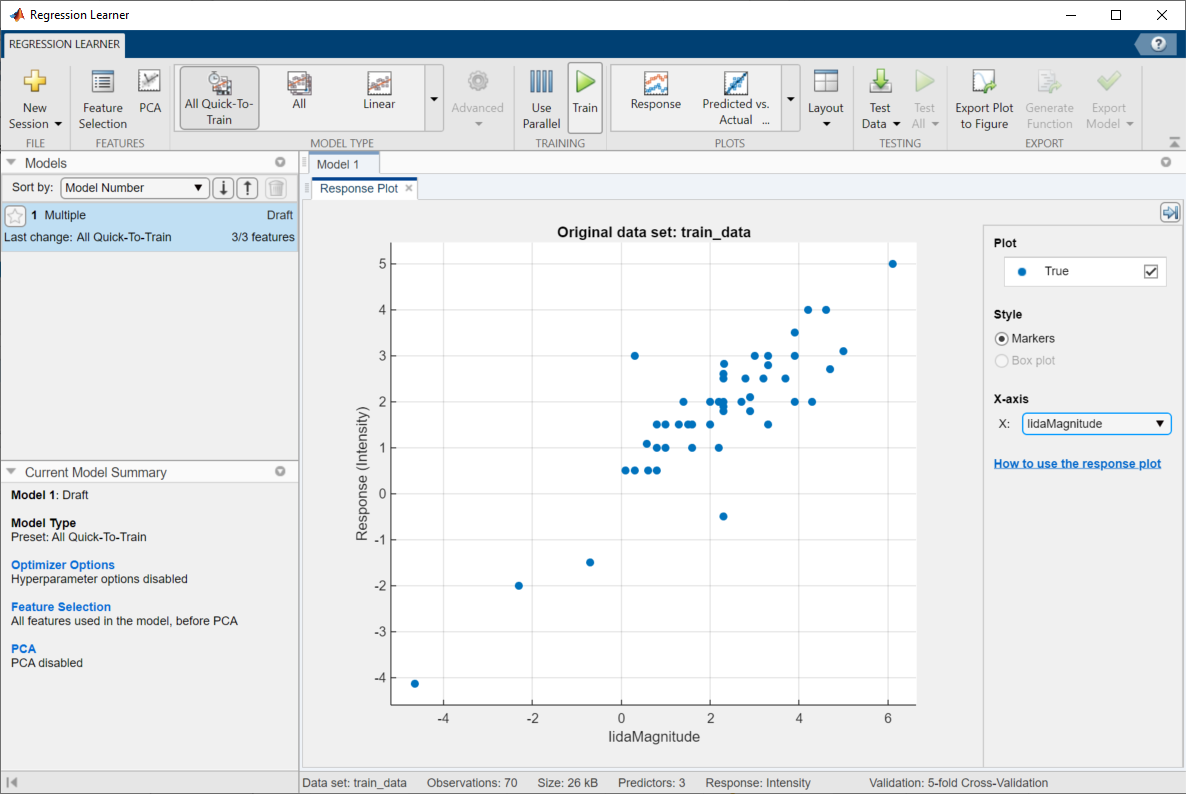

The model with the lowest root mean squared error (rmse) was selected as the model that we would explore further (in this case the option with the blue background in the Models tab).

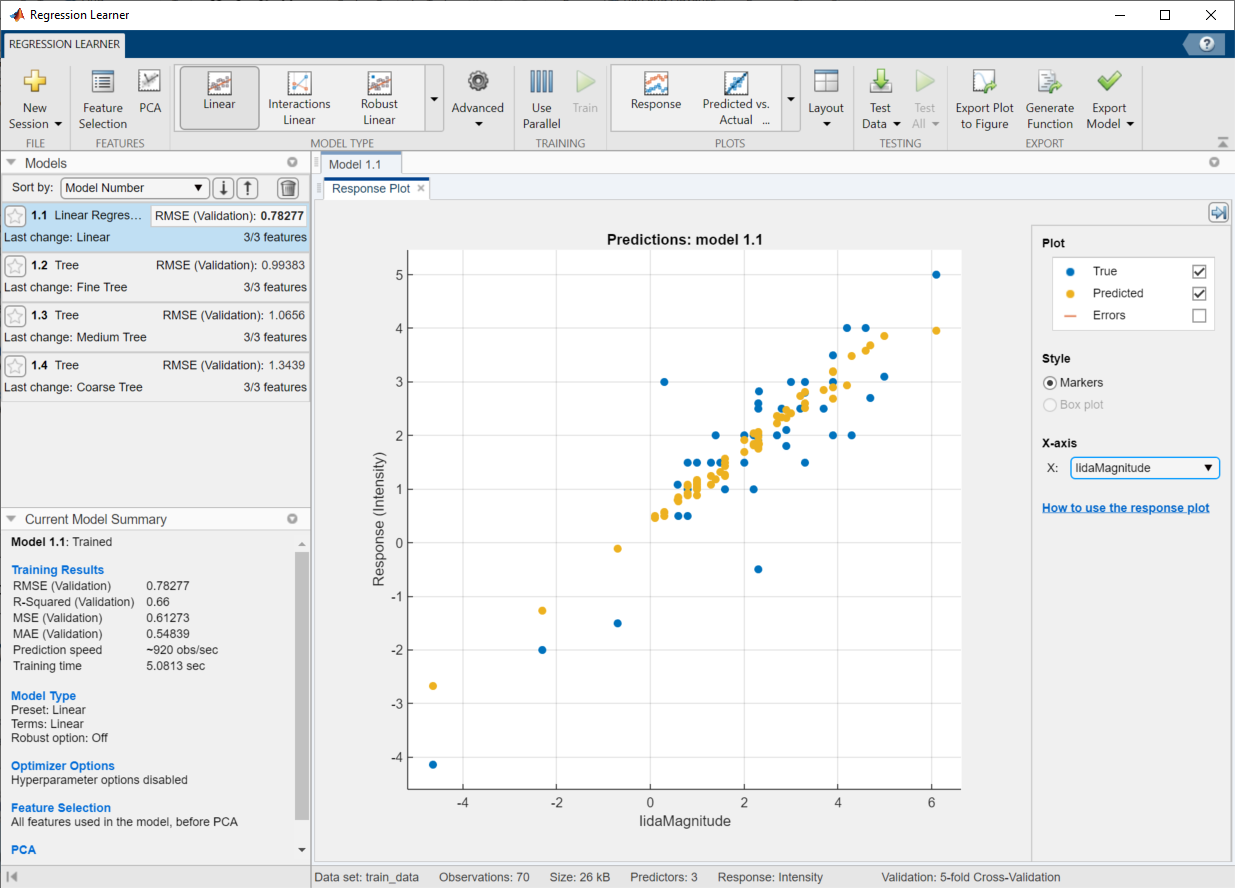

What can we do after obtaining and reviewing results?

In this case we decided to export the Machine Learning model to the workspace but you could generate the code for this function as well.

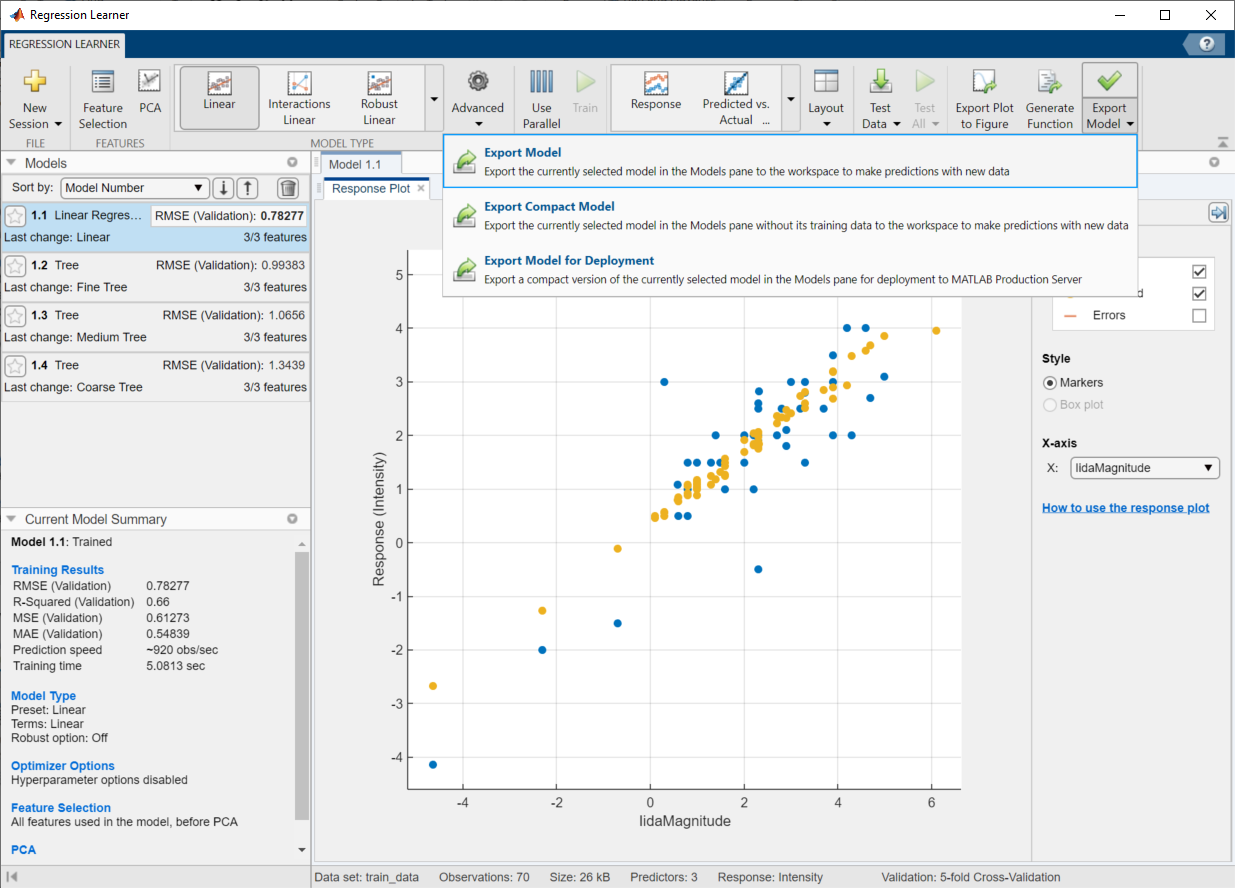

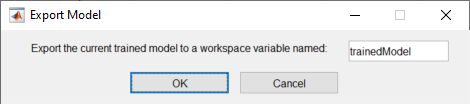

#### 8) Create a table for testing the trainedModel imported from 

####     the Regression Learner app

T=data2(1:2,[1:4,6:9])

T = 2×8 table
    Latitude    Longitude    EarthquakeMagnitude    IidaMagnitude    MaxHeight            Validity                     Location                Country   
    ________    _________    ___________________    _____________    _________    ________________________    __________________________    _____________

      -3.8        128.3              7.6                 1.5            2.8       {'questionable tsunami'}    {'JAVA TRENCH, INDONESIA'}    {'INDONESIA'}
     42.15       143.85              8.1                 2.7            6.5       {'definite tsunami'    }    {'SE. HOKKAIDO ISLAND'   }    {'JAPAN'    }


#### 9) Predicting the Species of the table T, using the trainedModel

yfit =trainedModel.predictFcn(T)

Unable to resolve the name 'trainedModel.predictFcn'.